### **Interactive Notes for Mapping between S-plane to Z-plane by Chien Jer Luen**

#### *Note: Please send an email to jerluen_chien@mymail.sutd.edu.sg if you happen to find any mistakes in the interactive notes :)*

Mapping from the s-plane to the z-plane is relatively simple. The mathematical relationship between s and z can be simple expressed as: 

$z = e^{sT}$.

The pole in the Laplace (or s) domain can also be expressed as: 


$$s = \sigma + j\omega_d, 
$$


where $\sigma, \omega_d$ can be expressed as: 


$$\sigma = -\zeta \omega_n$$


$\omega_d = \omega_n \sqrt{1-\zeta^2}$.

We can see that as $\zeta
$ varies, the damping frequency changes directly as a result.  

T = 0.1; % Sampling Time 
zeta = 0.63

zeta = 0.6300

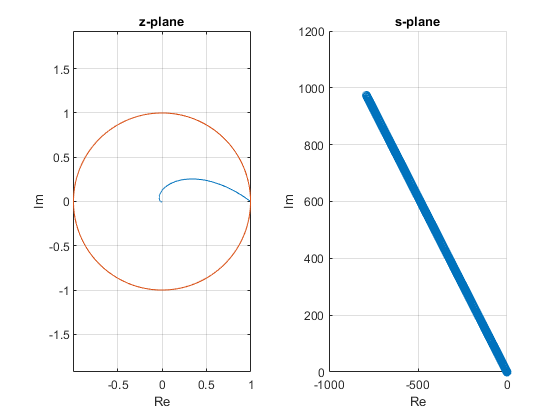

omega_n = linspace(0, 200*(2*pi), 20000);
sigma = -zeta*omega_n;
omega_d = omega_n*sqrt(1-zeta^2);

z = exp((-omega_n*zeta + 1i*(omega_d)*sqrt(1-zeta))*T);

f = figure;

tiledlayout(1,2);

nexttile
plot(z)
hold on;
plot(cos(omega_n),sin(omega_n))
axis equal
xlabel("Re")
ylabel("Im")
title('z-plane')
grid on

hold off

nexttile

scatter(sigma, omega_d)
xlabel("Re")
ylabel("Im")
ylim([0 1200])
xlim([-1000 0])
title('s-plane')
grid on

hold off

clf('reset')

We know the general solution for homogeneous LTI systems $\dot{x}(t) = Ax$ is in the form of 

$x(t) = e^{At}$.

Intuitively, if $\sigma$ < 0,  and the larger the magnitude of $\sigma$, the faster the system stabilises itself. Let's vary $\sigma$ and $\omega_d$ now and see what insights we get. 

One interesting question to ponder upon is: 

What happens if $s \to -\infty$? Where does it land in the z-plane?

angle = 6.2832;
omega_d = linspace(0, angle, 100);
sigma = -1.07;
s = sigma + 1i*(omega_d)

s =   -1.0700 + 0.0000i  -1.0700 + 0.0635i  -1.0700 + 0.1269i  -1.0700 + 0.1904i  -1.0700 + 0.2539i  -1.0700 + 0.3173i  -1.0700 + 0.3808i  -1.0700 + 0.4443i  -1.0700 + 0.5077i  -1.0700 + 0.5712i  -1.0700 + 0.6347i  -1.0700 + 0.6981i  -1.0700 + 0.7616i  -1.0700 + 0.8251i  -1.0700 + 0.8885i  -1.0700 + 0.9520i  -1.0700 + 1.0155i  -1.0700 + 1.0789i  -1.0700 + 1.1424i  -1.0700 + 1.2059i  -1.0700 + 1.2693i  -1.0700 + 1.3328i  -1.0700 + 1.3963i  -1.0700 + 1.4597i  -1.0700 + 1.5232i  -1.0700 + 1.5867i  -1.0700 + 1.6501i  -1.0700 + 1.7136i  -1.0700 + 1.7771i  -1.0700 + 1.8405i  -1.0700 + 1.9040i  -1.0700 + 1.9675i  -1.0700 + 2.0309i  -1.0700 + 2.0944i  -1.0700 + 2.1579i  -1.0700 + 2.2213i  -1.0700 + 2.2848i  -1.0700 + 2.3483i  -1.0700 + 2.4117i  -1.0700 + 2.4752i  -1.0700 + 2.5387i  -1.0700 + 2.6021i  -1.0700 + 2.6656i  -1.0700 + 2.7291i  -1.0700 + 2.7925i  -1.0700 + 2.8560i  -1.0700 + 2.9195i  -1.0700 + 2.9829i  -1.0700 + 3.0464i  -1.0700 + 3.1099i


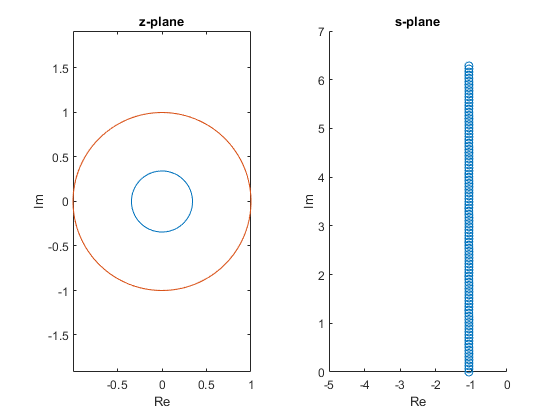


tiledlayout(1,2);
nexttile
z = exp(s);
plot(z) 
hold on
plot(cos(omega_n),sin(omega_n))
xlabel("Re")
ylabel("Im")
title('z-plane')
axis equal

nexttile
scatter(sigma*ones(length(omega_d),1), omega_d)
xlabel("Re")
ylabel("Im")
xlim([-5 0])
title('s-plane')

hold off

clf('reset')

Let's see what happens when you vary the value of the sampling time T. Increasing the value of T brings the z-poles closer towards the origin of the z-plane. Intuitively, we may think that the states converge at a faster rate because the z-poles closer to the origin of the z-plane. We will see that this is not true later. 

T = 1.93

T = 1.9300

sigma = -1

sigma = -1

omega_d = 2.7

omega_d = 2.7000

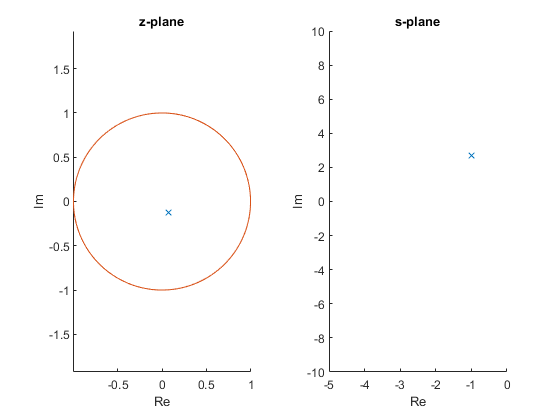

tiledlayout(1,2)

nexttile 
scatter(exp(sigma*T)*cos(omega_d*T), exp(sigma*T)*sin(omega_d*T), 'x')
hold on 
plot(cos(omega_n),sin(omega_n))
axis equal
xlabel("Re")
ylabel("Im")
title('z-plane')

nexttile
scatter(sigma, 1*omega_d, 'x')
xlabel("Re")
ylabel("Im")
xlim([-5 0])
ylim([-10 10])
title('s-plane')
hold off 

clf('reset')

Now, let's plot the analytical solutions for both the homogeneous LTI system $\dot{x}(t) = a
x$, using sampling times $T_1 = 0.1s , T_2 = 1s$, and set $a = -0.5$. We can see that even though the pole $T_2

$ is nearer to the origin in the z-plane, the continuous solutions for both systems are exactly the same. 

However, the discrete solution on the right converges a lot faster w.r.t to the system's timestep $k$ instead of the continuous time $t$. 

Therefore, the key insight here is that having a pole close to the origin (in the z-plane) does not necessarily mean that the system converges faster. It just means that it **converges faster w.r.t to the timestep **$k$** instead.**

T_1 = 0.1

T_1 = 0.1000

T_2 = 1 

T_2 = 1

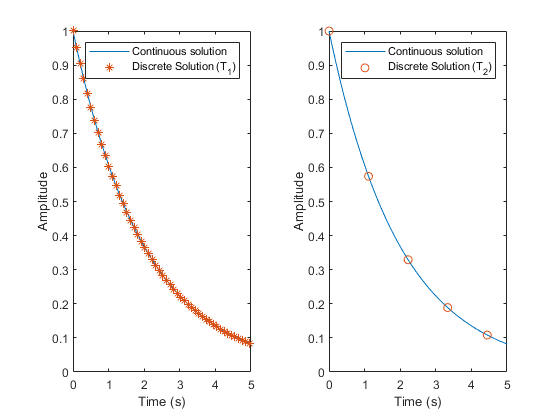

a = -0.5;
t = linspace(0, 10, 100);
k_1 = linspace(0, 100, 100);
k_2 = linspace(0, 10, 10);

tiledlayout(1,2);
nexttile
x_t = exp(a*t);
x_T1 = exp(a*k_1*T_1);
x_T2 = exp(a*k_2*T_2);
plot(t, x_t)
hold on
scatter(k_1*T_1, x_T1, '*')
xlim([0 5])
xlabel("Time (s)")
ylabel("Amplitude")
legend('Continuous solution','Discrete Solution (T_1)')
nexttile
plot(t, x_t)
hold on
scatter(k_2*T_2, x_T2)
xlim([0 5])
xlabel("Time (s)")
ylabel("Amplitude")
legend('Continuous solution','Discrete Solution (T_2)')
hold off